clc
clear all
close all
plot_counter=1;

sys modelinns

A=[1 -1.5 0.6];
B=[1 -0.8];
C=[1 -0.8 0.1];
T_s=0.1;

Question_mark='Q21-MV';
[uc,t,Status,tfinal,Noise]=Datagen_Stochastic(2,T_s,500,0.01,C);

Status = '-Cololerd NOISE-'

Titlework=[Question_mark,Status]

Titlework = 'Q21-MV-Cololerd NOISE-'

Assumption


d=1

d = 1

q=[1,0];
p=[1,-0.2];

p0=p(1);
p1=p(2);

na=size(A,2);
nb=size(B,2);
alpha=10^4;
P=alpha*eye(na+nb-1);
Theta=0.5*ones(na+nb-1,1);
Theta(1)=1;
Phi=zeros(na+nb-1,1);
Lambda=1;


T=[0 0];

N=numel(t);
var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);
error=zeros(N,1);

y   =zeros(N,1);
u   =zeros(N,1);
uf  =zeros(N,1);
yf  =zeros(N,1);

%for i=max(na,nb)+d0-1:N
for i=max(na,nb)+d:N
    R=Theta(1:2)';
    S=Theta(3:4)';
    ThetaCurve(i,:)=[Theta'];

    y(i) = -A(2:end)*[y(i-1:-1:i-2)]+B*[u(i-1:-1:i-2)]+Noise(i);
    yf(i)=(-p(2:end)*[yf(i-1)]      +q*y(i:-1:i-1))/p(1);

    u(i)=(-R(2:end)*[u(i-1)]+T*[uc(i:-1:i-1)]-S*[y(i:-1:i-1)])./R(1);
    if abs(u(i))>100
        u(i)=sign(u(i))*100;
    end
    uf(i)=((-p(2:end)*uf(i-1)+q*u(i:-1:i-1)))/p(1);

    var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
    var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;

            RLS

    Phi=[uf(i-d:-1:i-1-d)' yf(i-d:-1:i-1-d)']';
    K=P*Phi*(Lambda+Phi'*P*Phi)^(-1);
    P=(eye(na+nb-1)-K*Phi')*P/Lambda;
    Error=y(i)-Phi'*Theta;
    Theta=Theta+K*Error;
    error(i)=Error;
end

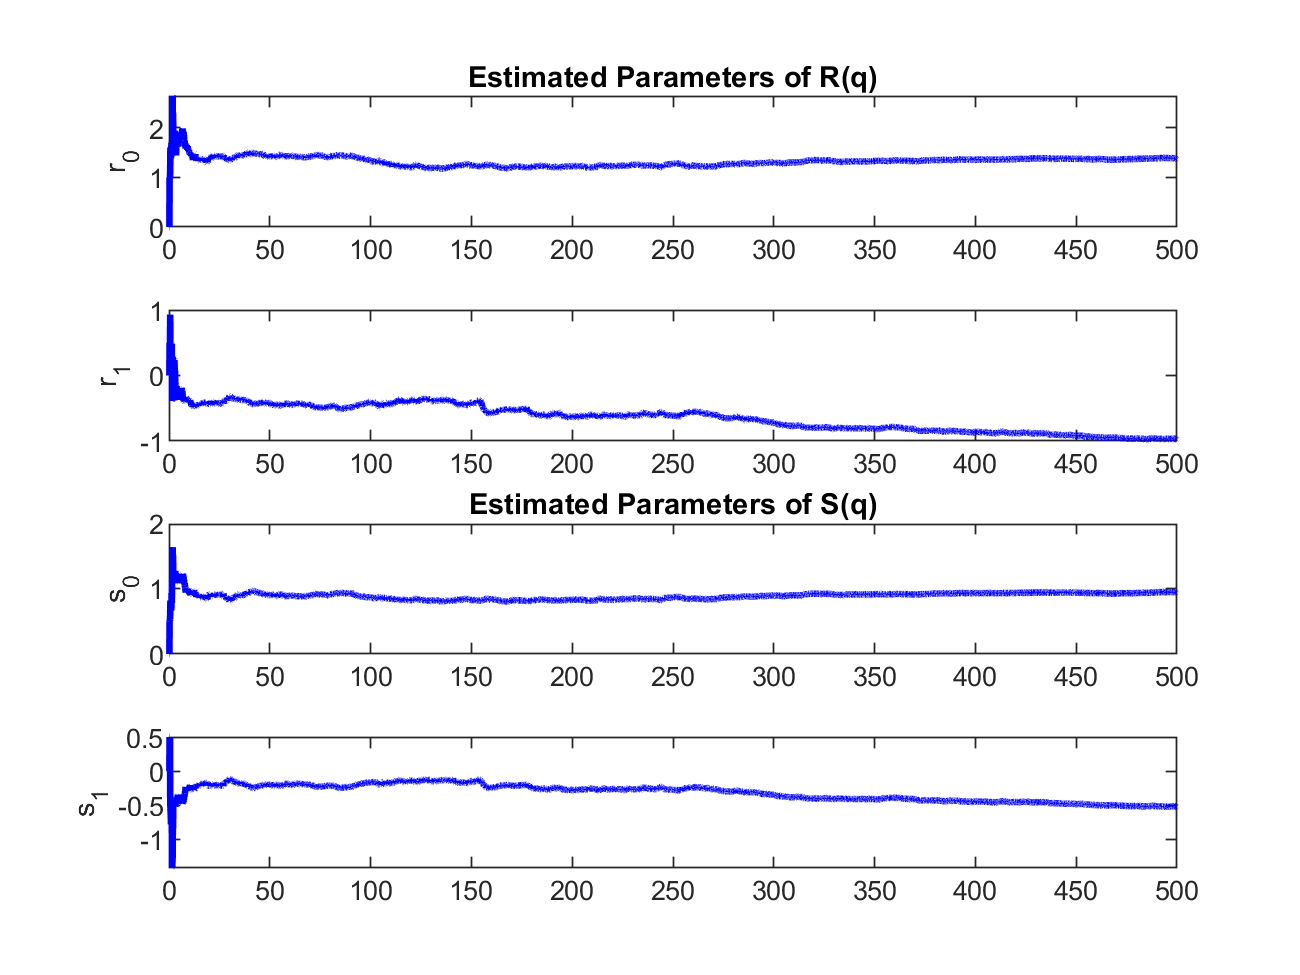

figure(1);
subplot(411);
plot(t',ThetaCurve(:,1),'b','lineWidth',2);
hold on;
ylabel('r_0');
title('Estimated Parameters of R(q)');

subplot(412);
plot(t',ThetaCurve(:,2),'b','lineWidth',2);
hold on;
ylabel('r_1');

subplot(413);
plot(t',ThetaCurve(:,3),'b','lineWidth',2);
hold on;
ylabel('s_0');
title('Estimated Parameters of S(q)');

subplot(414);
plot(t',ThetaCurve(:,4),'b','lineWidth',2);
hold on;
ylabel('s_1');
print(gcf,[Titlework , num2str(plot_counter) ' RLS convergence.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

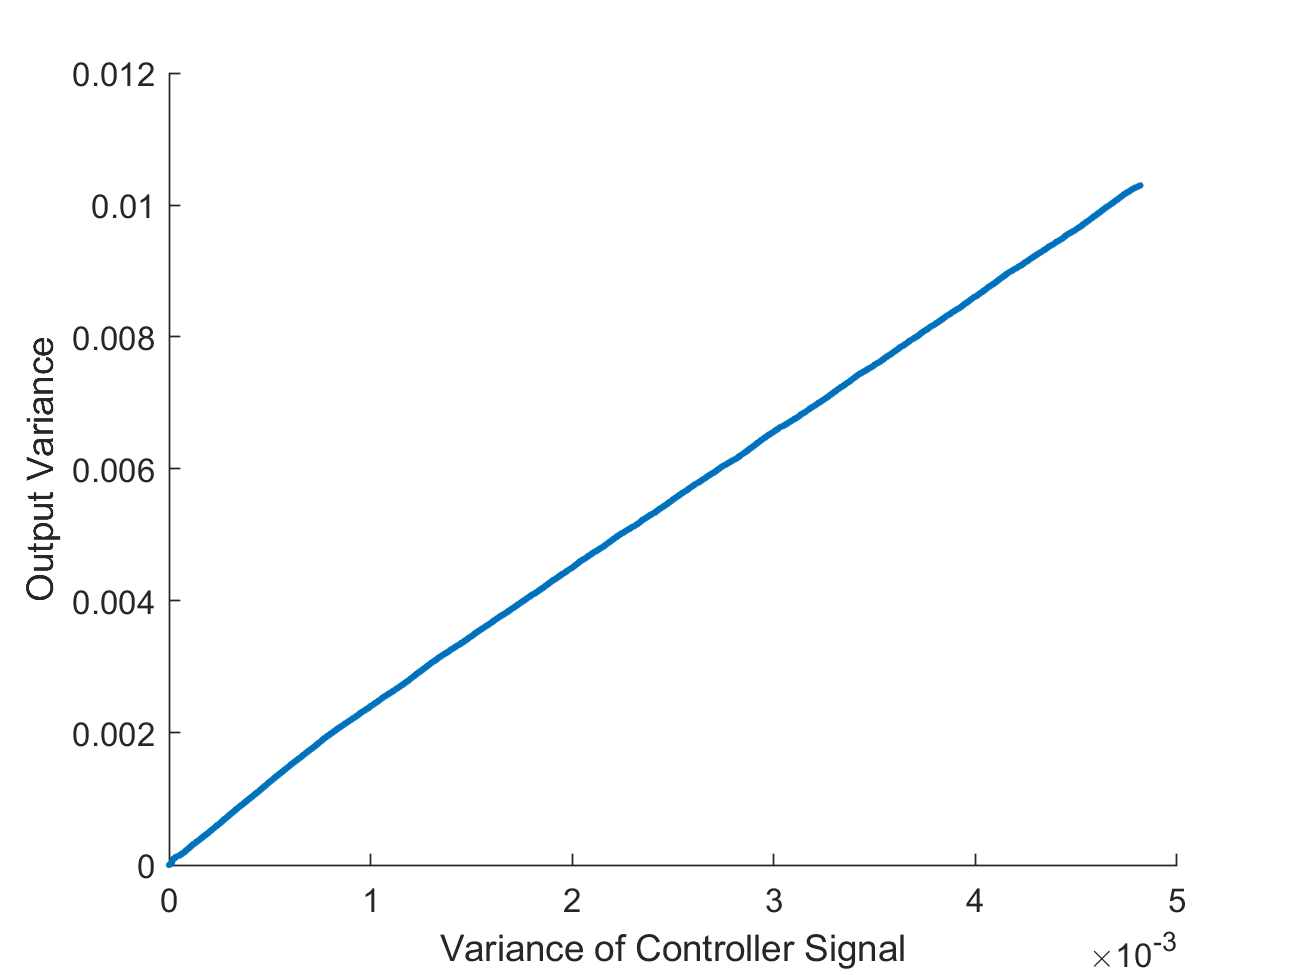

figure
hold on
plot(var_u,var_y,'.')
xlabel('Variance of Controller Signal')
ylabel('Output Variance')

## Output and control signal plotting

General Input v.s. Output

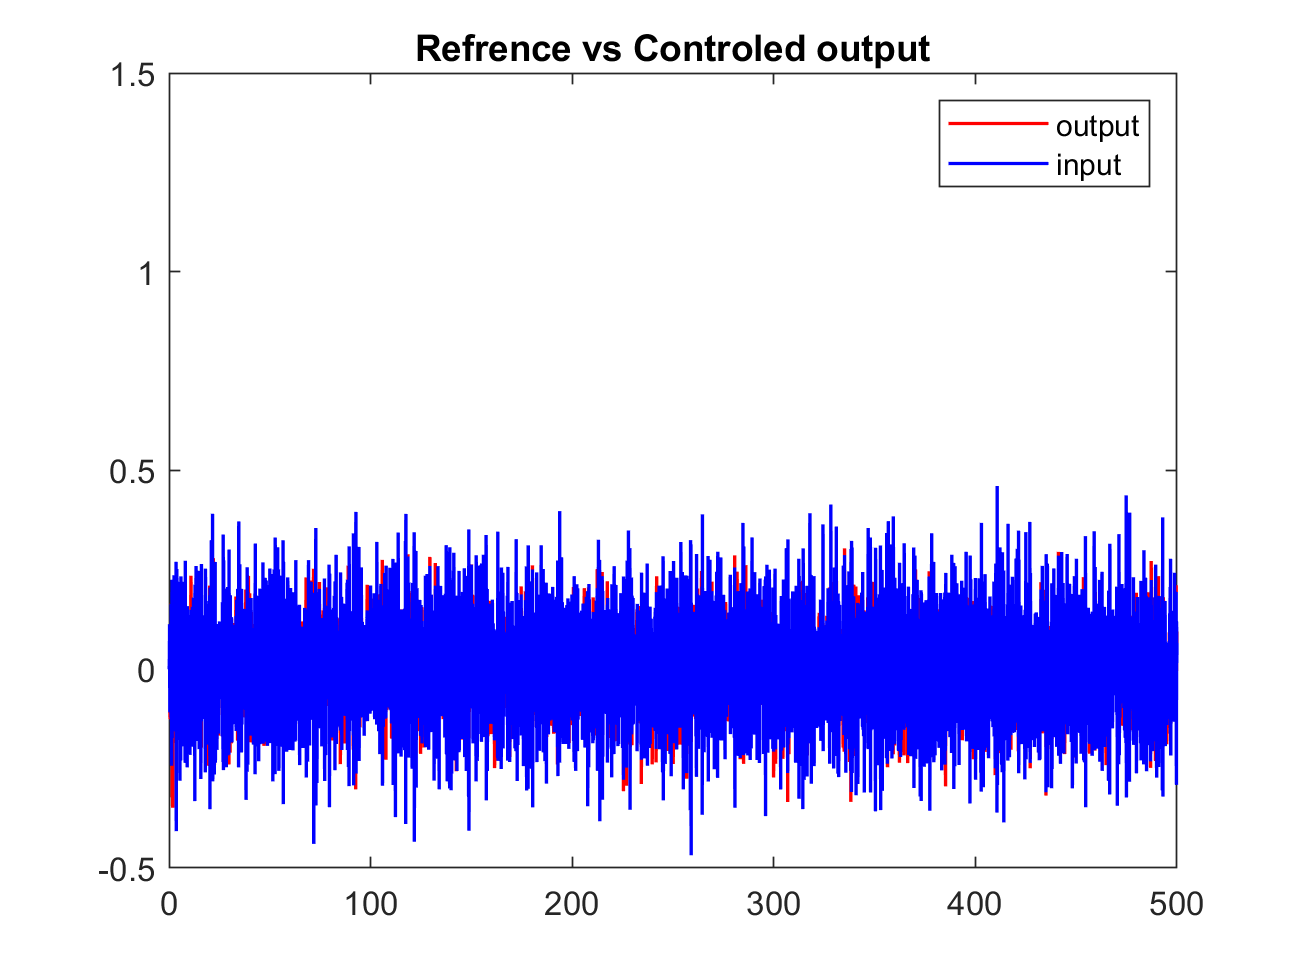

figure()
plot(t,y,'r-',t,Noise,'b-','LineWidth',1)
title('Refrence vs Controled output')
legend('output','input')
xlim('auto')
ylim([-0.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Noise vs Controled output.png'],'-dpng','-r400');

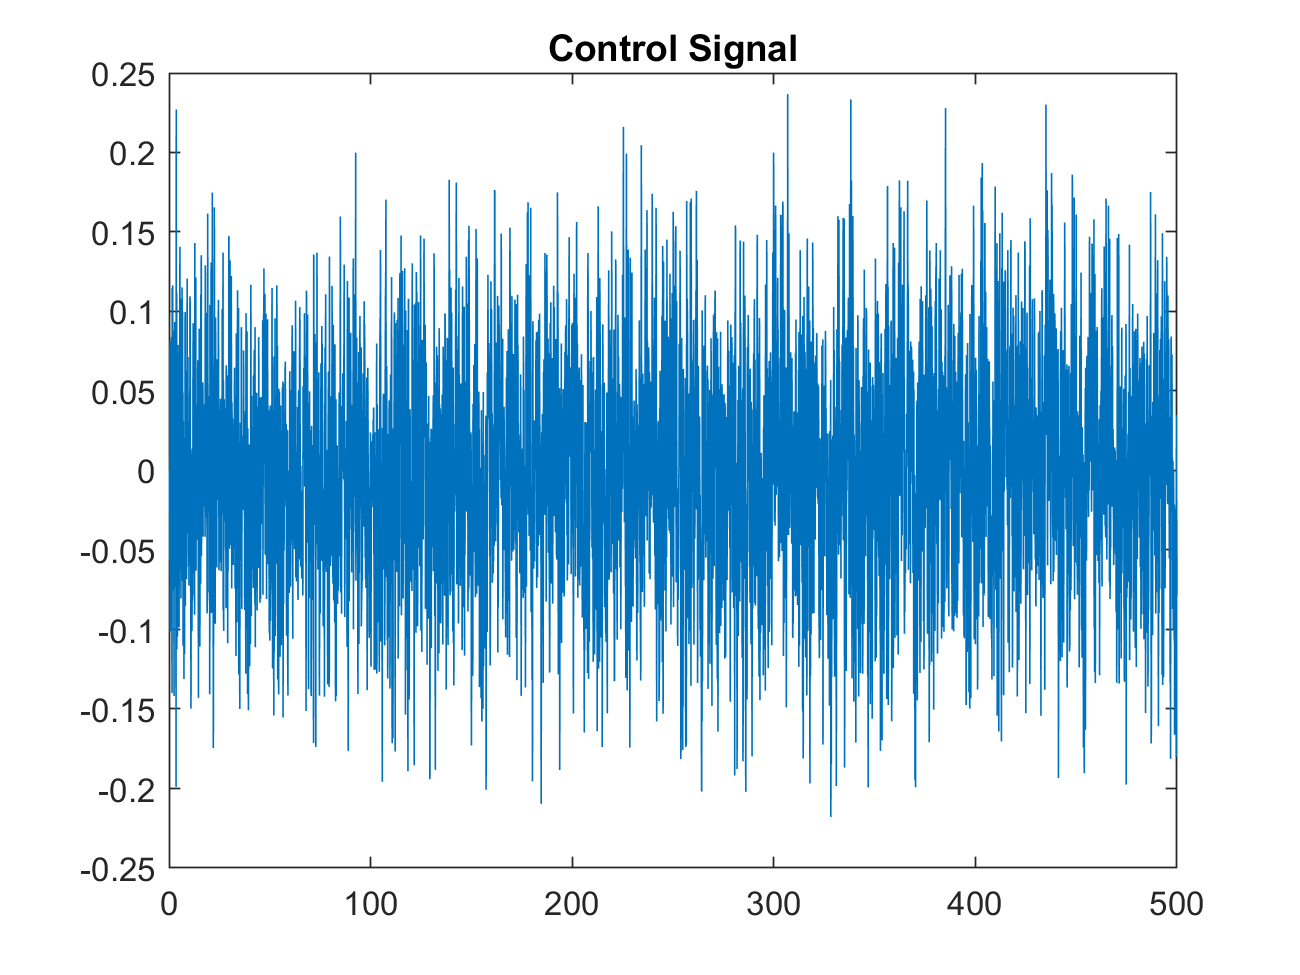

plot_counter=plot_counter+1;

plot(t,u)
title('Control Signal')
% xlim('auto')
% ylim([-1.5 1.5])
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Variance plotting

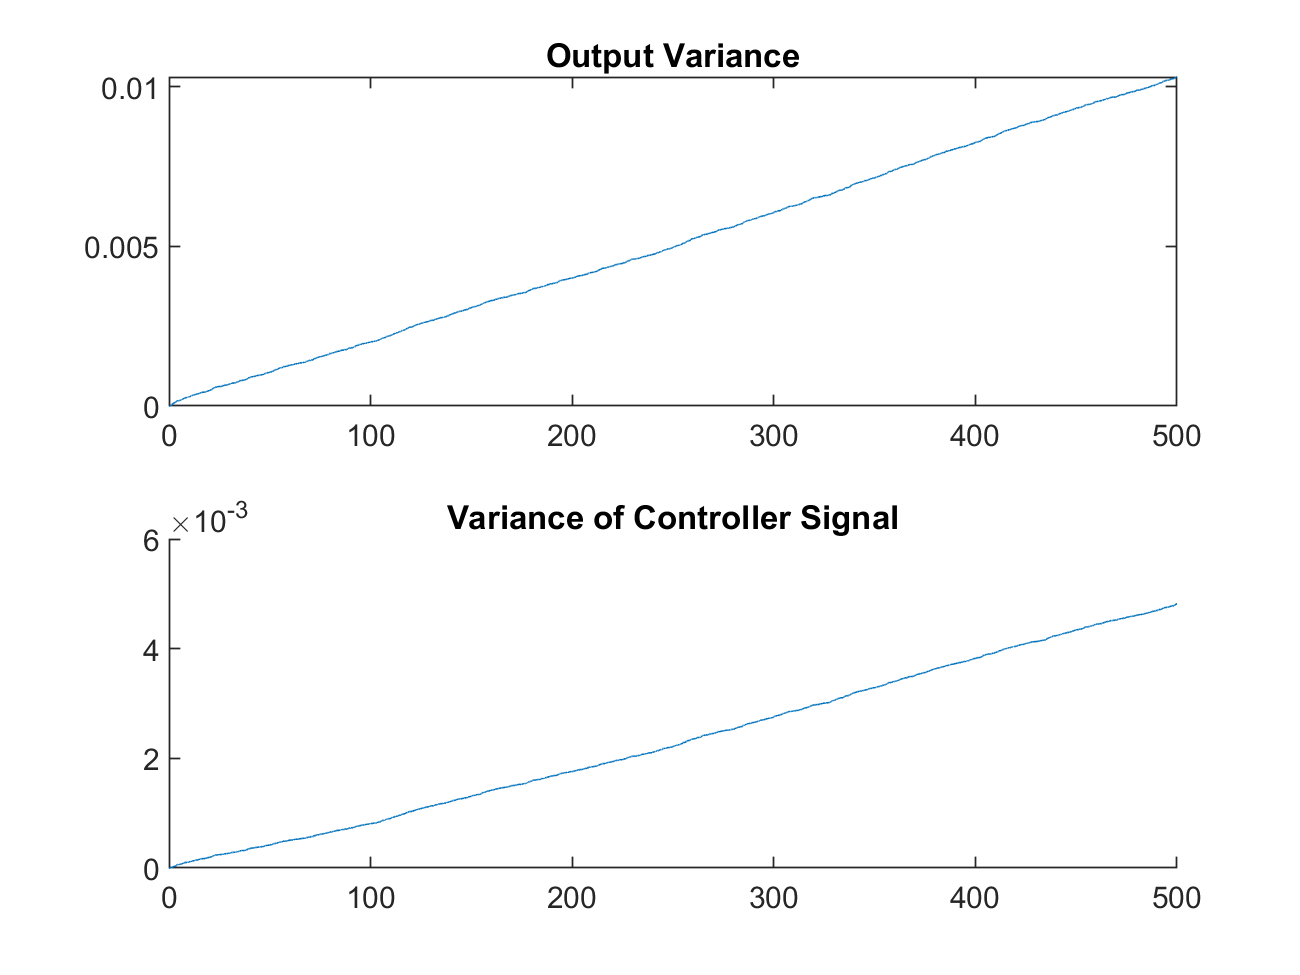

figure
subplot(211)
plot(t,var_y)
hold on
title('Output Variance')

subplot(212)
hold on
title('Variance of Controller Signal')
plot(t,var_u)
print(gcf,[Titlework , num2str(plot_counter) ' Variance.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Mean plotting

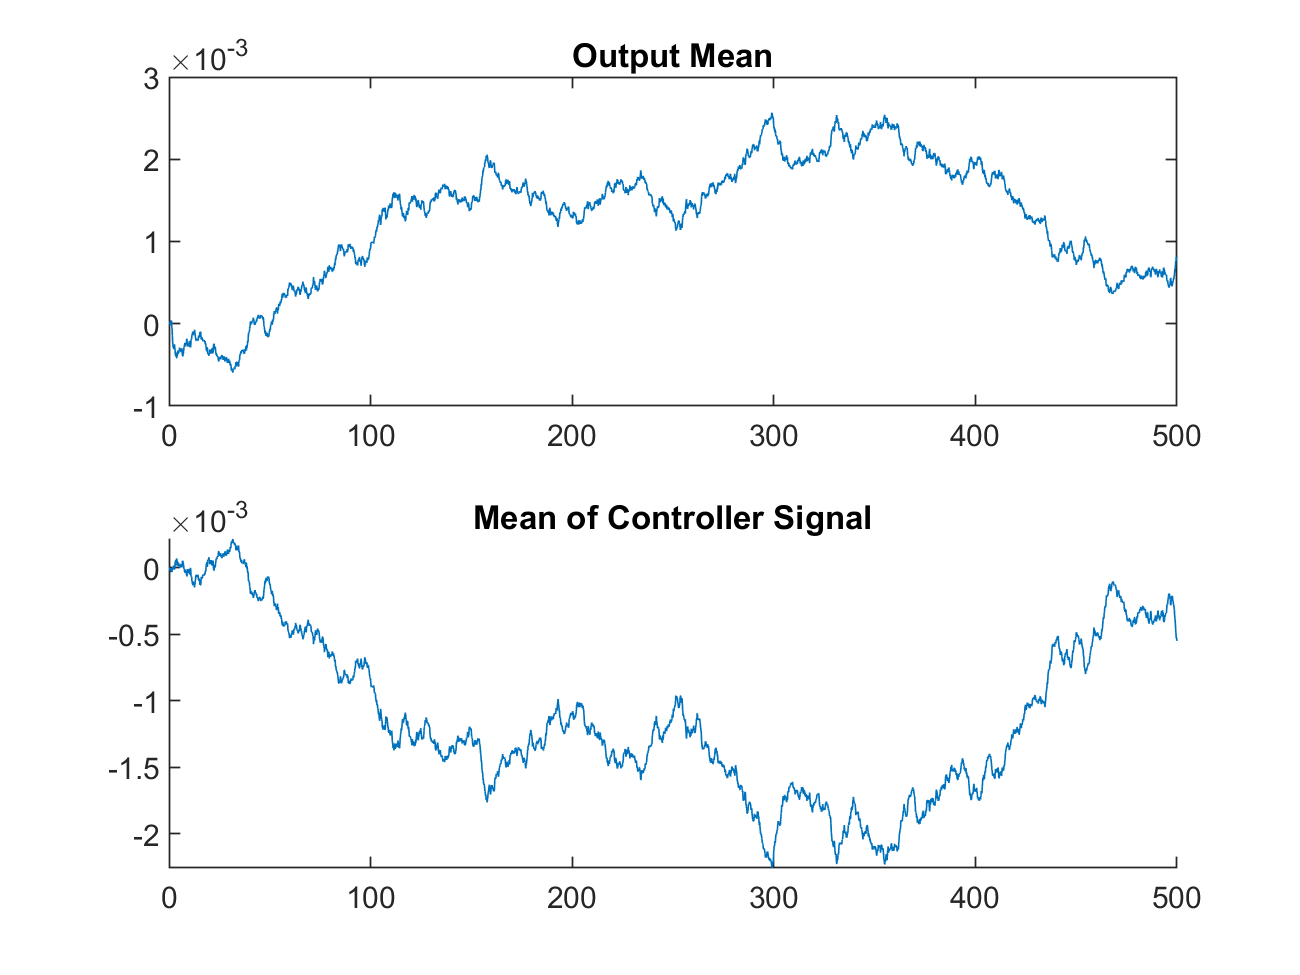

figure
subplot(211)
plot(t,mean_y)
hold on
title('Output Mean')

subplot(212)
hold on
plot(t,mean_u)
title('Mean of Controller Signal')
print(gcf,[Titlework , num2str(plot_counter) ' mean.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Accumulated loss plotting

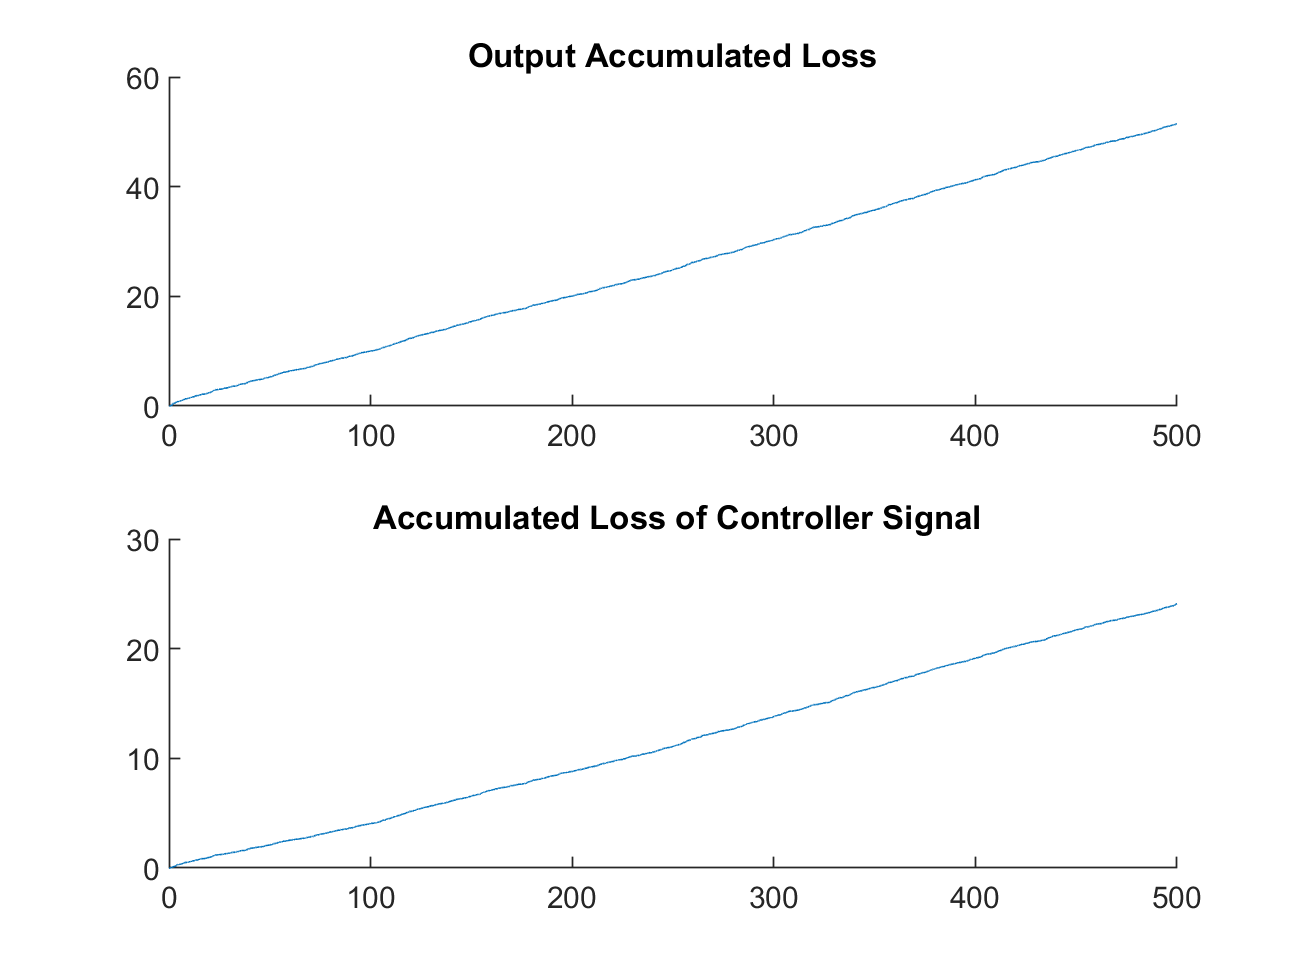

figure
subplot(211)
hold on
plot(t,ACLS_y)
title('Output Accumulated Loss')

subplot(212)
hold on
title(' Accumulated Loss of Controller Signal')
plot(t,ACLS_u)
print(gcf,[Titlework , num2str(plot_counter) ' Accumulated Loss.png'],'-dpng','-r400');

plot_counter=plot_counter+1;